SIMULATION study showing where harmonic flow excles in capturing recurrent cyclic interactions in a netework with 1-cycle while Granger casuality and structural equation struggle. 

(C) 2026 Moo K. Chung, 

University of Wisconsin-Madison

### Ground Truth 

Building Directed Cyclic Graph (DCG): a directed graph that contains one or more cycles. We build cycle-only ground truth with 4-nodes indexed as 1, 2, 3 and 4. We then add two additional nodes 5 and 6 and connect node 5 to node 2, and node 6 to node 4 

clear; clc; 
Nodes = [cos((0:3)'*2*pi/4) sin((0:3)'*2*pi/4)];  
Edges = [1 2; 2 3; 3 4; 4 1];
X     = [2; 3; 3; 2];   % edge flow strength, edges are indexed following 'Edges'.

Nodes = [Nodes;  
         0   1.8;  % node 5 above node 2
         0  0.2];  % node 6 below node 4

% 
Edges = [Edges;
         2 5;      % edge from 2 -> 5
         6 4];     % edge from 6 -> 4

We then assign an edge flow X along the edge directions and vary the strength of the circulation by attenuating the magnitudes of the remaining edge flows. Subsequently, we simulate random edge flows using a vector autoregressive model with X as the ground truth, and obtain noisy observed node time series Z.

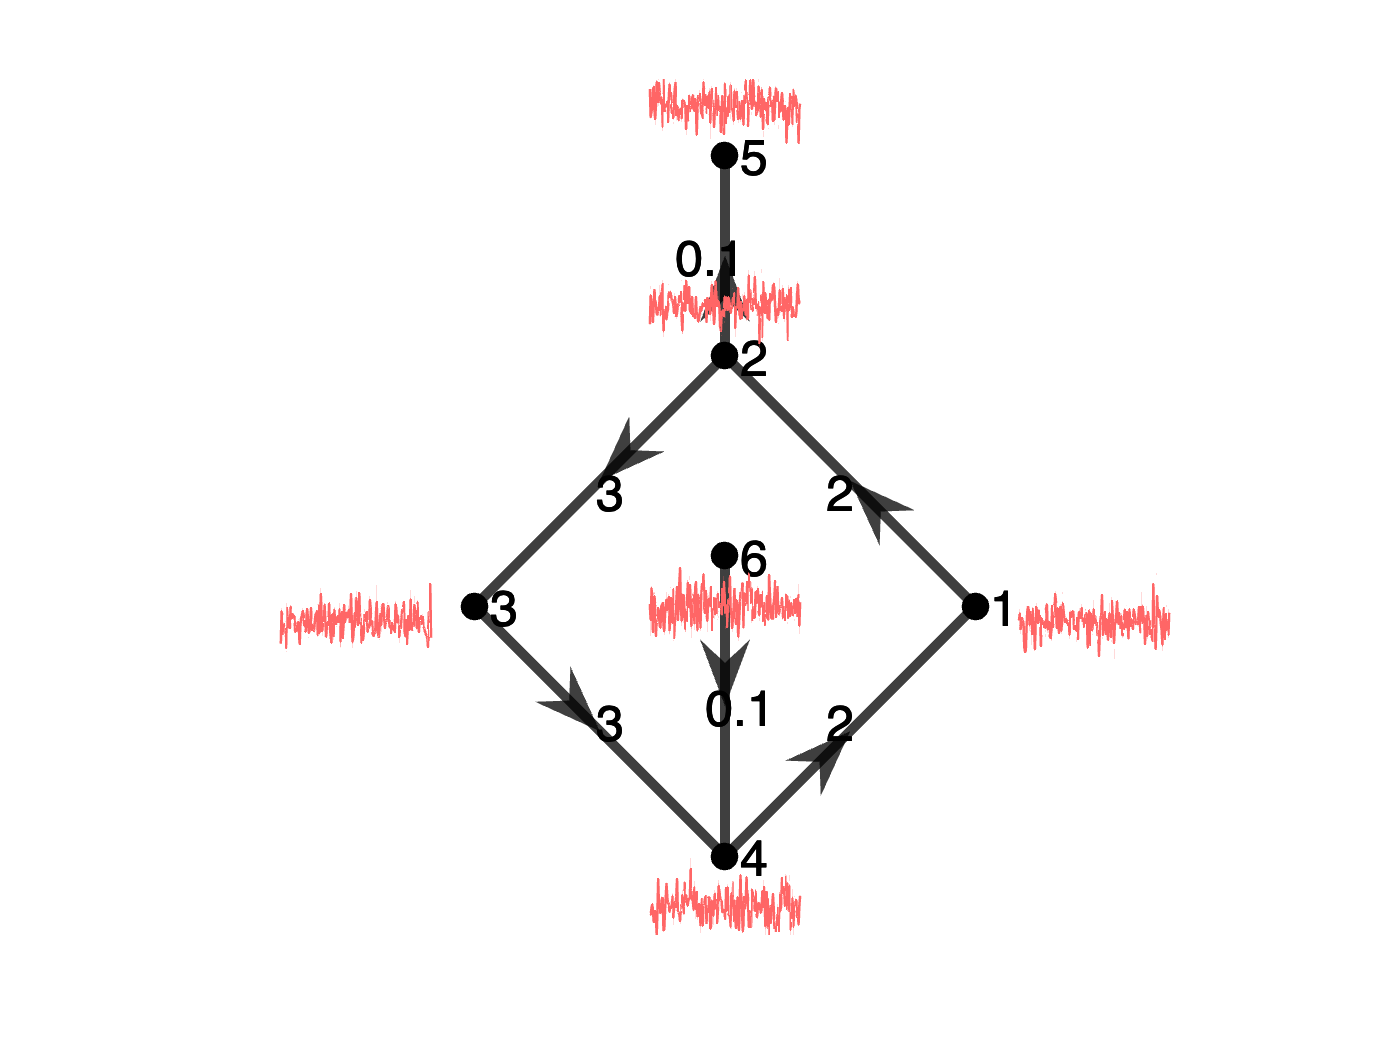

%X = [X; 0; 0];   % Only circulation
X = [X; 0.1; 0.1];   % strong circulation
%X = [X; 5; 5];      % weak circualtion
%X = [X; 100; 100];  %super weak circualtion
figure;  graph_directed_plot(Nodes, Edges, X);
Z= VAR_graph(Edges, X, 4,1);
graph_directed_plot(Nodes, Edges, X);
graph_overlay_timeseries(Nodes, Z)

In the simulation, the ground truth is a cyclic structure encoded in the connectivity matrix, and the goal is to assess whether the proposed method can accurately recover the underlying cyclic flow.

X_truth = [2; 3; 3; 2; 0; 0]'; %ground truth edge flow
C_truth = graph_edge2matrix(Edges, X_truth)

C_truth =      0     2     0    -2     0     0
    -2     0     3     0     0     0
     0    -3     0     3     0     0
     2     0    -3     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


To perform random simulations, we first generate random time series a priori and save them, so that exactly the same realizations are used across all methods. This avoids feeding different time series to different methods and ensures a fair comparison.

noise_levels = [0.1, 1, 10];
Na = numel(noise_levels);
nTrials = 100; %10 trials for faster performance. change it to 100 for publication. 

for a = 1:Na
    sigma = noise_levels(a);  
    for t = 1:nTrials
        Z = VAR_graph(Edges, X, 4, sigma);     % generate one random realization
        Zall(:,:,a,t) = Z;         % store [T x K x Na x nTrials]
    end
end

%save simulationZ.mat  Zall 


### Granger Causality

The implementation follows linear Granger causality within a vector autoregressive (VAR) framework, where the model order is selected using information criteria and directional dependence is quantified via residual-based variance comparisons following Geweke (1982):

Geweke, J. Measurement of linear dependence and feedback between multiple time series. *Journal of the American statistical association* 77 (1982): 304-313.

noise_levels = [0.1, 1, 10];
Na = numel(noise_levels);
nTrials = 10; %10 trials for faster performance. change it to 100 for publication. 

load simulationZ.mat

% Cosine similarity for Granger causality
cos_gc = zeros(Na, nTrials);


for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);                 % stored as [K x T]
        % VAR_fit expects X as [N x T] = [nodes x time]
        [A_est, X_pred, GC_matrix, P] = VAR_fit(Z);   
        % Convert p-values to connectivity strength, Smaller p-value = stronger evidence of Granger causality
        What = 1 - GC_matrix;                          % simple monotone conversion
        scG = VAR_score(What, C_truth);
        cos_gc(a,t) = scG.cosine;
    end
end

mGC = mean(cos_gc, 2, 'omitnan');
sGC = std(cos_gc, 0, 2, 'omitnan');

disp(table(noise_levels(:), mGC, sGC, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.38873      0.099629 
       1      0.36104      0.059558 
      10      0.34213      0.097131 



### Nonlinear Structural Equation Model (SEM)

The function **SEM_nonlinear** fits, for each node $X_j$, a nonlinear additive regression model using all other variables as predictors:


$$X_j = f_j(X_{-j}) + e_j, \qquad j=1,\dots,p,$$


where $X_{-j}$ denotes all variables except $X_j$, and $f_j$ is approximated by a **Generalized Additive Model (GAM)** fitted using the built-in Matlab function **fitrgam**. Suppose the data matrix is


$$Z = [X_1,\dots,X_p] \in \mathbb{R}^{n \times p}$$


where each column is a variable and each row is an observation. For a fixed node $X_j$, the code takes column $j$ as the response variable and uses all columns of $Z$ as predictors, except that the $j$-th predictor column is set to zero so that $X_j$ is not used to predict itself. Then **fitrgam **fits a nonlinear regression model


$$X_j = f_j(X_1,\dots,X_{j-1},X_{j+1},\dots,X_p).$$
 

GAM approximates the regression function as a sum of one-dimensional nonlinear functions of each predictor. For predicting $X_j$, it fits a model of the form


$$\hat{f}_j(X_1,\dots,X_{j-1},X_{j+1},\dots,X_p) =\beta_0 + \sum_{i \neq j} g_i(X_i),$$


where each $g_i(\cdot)$ is a smooth nonlinear function estimated from the data. This model is also known a **Causal Additive Model** (CAM) in causal inference introduced by Bühlmann, P., Peters, J. and Ernest., J., 2014 [CAM: Causal additive models, high-dimensional order search and penalized regression](https://projecteuclid.org/journalArticle/Download?urlId=10.1214%2F14-AOS1260), Annals of Statistics 42: 2526-2556.

After fitting the model for node $j$, we denote the fitted function by


$$\widehat{X}_j(t) = \hat{f}_j\bigl(X_1(t),\dots,X_{j-1}(t),X_{j+1}(t),\dots,X_p(t)\bigr).$$


After fitting the model for node $j$, we computes the prediction error


$$\mathrm{MSE}_0 = \frac{1}{n}\sum_{t=1}^n \bigl(X_j(t)-\widehat{X}_j(t)\bigr)^2.$$


Note $\mathrm{MSE}_0$ only quantifies how well the function $\hat{f}_j$ predicts $X_j$ using all variables jointly, but it does not tell us which variables are responsible for this prediction accuracy. Therefore, $\mathrm{MSE}_0$ alone cannot be used to infer directed relationships $X_i \to X_j$. To isolate the effect of $X_i$, we must compare the prediction error before and after removing the information carried by $X_i$. We quantify the contribution of each predictor using **Permutation Importance, i**ntroduced in Breiman, L. 2001,[ Random forests](https://link.springer.com/article/10.1023/a:1010933404324). *Machine learning* 45:5-32. 

To assess the contribution of a specific variable $X_i$, we remove the information carried by $X_i$ by randomly permuting its values across samples, while keeping all other predictors unchanged. This breaks the association between $X_i$ and $X_j$ without altering the fitted model.

Let $\widehat{X}_j^{(i)}(t)$ denote the predictions obtained after permuting $X_i$. The corresponding prediction error is


$$\mathrm{MSE}_1^{(i \to j)} = \frac{1}{n}\sum_{t=1}^n \bigl(X_j(t)-\widehat{X}_j^{(i)}(t)\bigr)^2.$$


The importance of $X_i$ for predicting $X_j$ is then defined as


$$W_{ij} = \mathrm{MSE}_1^{(i \to j)} - \mathrm{MSE}_0,$$


which measures how much the prediction error increases when the information in $X_i$ is disrupted. If permuting $X_i$ leads to a large increase in error, then $X_i$ plays an important role in predicting $X_j$. If the change is small, then $X_i$ contributes little to the prediction. Repeating this procedure for all pairs $(i,j)$ yields a weighted directed matrix $W = (W_{ij})$, where larger values indicate stronger nonlinear predictive contribution from $X_i$ to $X_j$. However, a single permutation can introduce variability due to randomness in the shuffling. To obtain a more stable estimate, the permutation step is typically repeated multiple times and averaged. In the current implementation,  the importance is estimated using a single permutation for a faster estimate. 

Contribution: Although the individual components are well established, their combination in nonlinear SEM is not standard. In particular, using permutation importance to extract a directed dependency matrix from node-wise nonlinear SEM fits is novel. This provides a simple, scalable, and model-agnostic way to quantify directed nonlinear influence, offering an alternative to traditional structure learning methods.

load simulationZ.mat

%Cosine similarity added
cos_nonlinSEM = zeros(Na, nTrials);
%Will take a while
for a = 1:Na
    for t = 1:nTrials
        Z=Zall(:,:,a,t);          % [T x K] from simulator
        out = SEM_nonlinear(Z.');             % out.W_inst is [K x K], i -> j
        scT = VAR_score(out.W_inst, C_truth);
        cos_nonlinSEM(a,t) = scT.cosine;         % <— FIX: store into correct variable
    end
end

mSEMnl = mean(cos_nonlinSEM, 2, 'omitnan');
sSEMnl = std(cos_nonlinSEM, 0, 2, 'omitnan');

disp(table(noise_levels(:), mSEMnl, sSEMnl, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.36821      0.029944 
       1      0.37726      0.038973 
      10      0.37912      0.033612 



### Cyclic Causal Discovery (CCD)

Let $Z=[Z_1,\dots,Z_K]\in\mathbb{R}^{T\times K}$ denote the observed variables, where $T$ is the number of samples and $K$ is the number of variables. Richardson’s Cyclic Causal Discovery (CCD) algorithm aims to recover causal structure in the presence of feedback (cycles) by exploiting conditional independence relations. The method proceeds in four steps. 

#### **1) Skeleton Extraction** 

It estimates an undirected skeleton by removing edges $(i,j)$ whenever $Z_i$ and $Z_j$ are conditionally independent over seperating set $S$, which is denoted as SepSet{i,j} in the code. 


$$Z_i \perp Z_j \mid S.$$
 

Simple Pearson correlation cannot distinguish direct relationships from indirect or spurious ones. Instead of testing whether $Z_i$ and $Z_j$ are directly correlated, we tests whether they are still related after removing the influence of variables in $S$. This is tested through the sample partial correlation between $Z_i$ and $Z_j$ given the variables in $S$. If the partial correlation is close to zero, then $Z_i$ and $Z_j$ are treated as conditionally independent given $S$ (under Gaussian assumption). Note if $S=\emptyset$, then the test reduces to the ordinary Pearson correlation. The partial correlation can be computed using the sample covariance matrix $\Sigma$ of $Z$ (equivalently this can be done using samaple correlation matrix). Let $\Sigma_{ijS}$ denote the submatrix indexed by the variables $\{i,j\} \cup S$. Define $P = (P_{ij}) =  \Sigma_{ijS}^{-1}.$ The inverse covariance matrix encodes conditional dependencies: zeros in $P$ correspond to conditional independence. The partial correlation between $Z_i$ and $Z_j$ given $S$ is computed as


$$\rho_{ij \mid S} = -\frac{P_{12}}{\sqrt{P_{11} P_{22}}}.$$


If $\rho_{ij \mid S} \approx 0$, then $Z_i$ and $Z_j$ are treated as conditionally independent, and the edge $(i,j)$ is removed. 

The algorithm then extracts the 1-skeleton by systematically applying this test across all pairs of variables. Starting from a fully connected undirected graph, for each pair $(i,j)$ the method searches over conditioning sets $S$ of increasing size $|S|$, where $S \subset (N_i \cup N_j)\setminus\{i,j\}$ and $N_i$ denotes the current neighbors of node $i$. For each candidate set $S$, the partial correlation $\rho_{ij\mid S}$ is computed and converted into a $p$-value. If there exists at least one set $S$ such that $p_{ij\mid S} > \alpha$ (currently set at 0.01), then $Z_i$ and $Z_j$ are treated as conditionally independent given $S$, and the edge $(i,j)$ is removed. This procedure is repeated iteratively for all pairs and all conditioning set sizes until no further edges can be removed. The resulting adjacency matrix $A=(A_{ij})$ defines an undirected graph, called the **skeleton**, which retains only those edges that cannot be explained away by conditional independence.

Limitation of this approach is its reliance on the inversion of covariance (or correlation) submatrices, which can become unstable in the presence of strong correlations or limited sample size. When $Z_i$ are highly correlated, $\Sigma$ becomes nearly singular, and its inverse is numerically unstable. This leads to unreliable estimates of $\rho_{ij\mid S}$ and consequently unstable $p$-values for the conditional independence test. This issue is particularly severe in high-dimensional settings where $T \ll K,$or when strong multicollinearity exists among variables. In such cases, even small perturbations in the data can lead to large fluctuations in the inverse matrix, resulting in inconsistent edge removal decisions. Furthermore, as the size of the conditioning set $|S|$ increases, the dimensionality of $\Sigma_I, \quad I=\{i,j\}\cup S,$ grows, exacerbating the instability and reducing statistical power. This can lead to both false positives (retaining spurious edges) and false negatives (removing true edges). Thus, the method suffers from the fundamental limitation in this particular simulation. 

#### 2) Collider Detection

The second step introduces directionality into the undirected graph obtained above. The algorithm identifies colliders. A collider is a fork in a directed graph having the form $i \to k \leftarrow j$. In this case, $k$ is called a collider because the two incoming edges collide at $k$. If $i$ and $j$ are both adjacent to $k$, but $i$ and $j$ are not adjacent, then $(i,k,j)$ is an unshielded triple. If $k\notin \mathrm{SepSet}(i,j)$, the triple is oriented as $i \to k \leftarrow j.$

After the undirected skeleton $A$ has been estimated, the algorithm examines each node $k$ and its current neighbors


$$N_k = \{i : A_{ik}=1\}.$$


If $k$ has at least two neighbors, the algorithm considers every unordered pair $(i,j)$ from $N_k$. For each such pair, it checks whether $i$ and $j$ are themselves adjacent. If 


$$A_{ik}=1, \qquad A_{jk}=1, \qquad A_{ij}=0,$$


then $(i,k,j)$ forms an unshielded triple. The algorithm then consults the separating set obtained during skeleton extraction. If


$$k \notin \mathrm{SepSet}(i,j),$$


the triple is oriented as a collider, $i \to k \leftarrow j.$

In the code, this is implemented by setting

orient(i,k) = 1, orient(j,k) = 1.

#### 3) Propagation Rule

After Collider Detection, only a subset of edges are oriented. We apply additional Propagation Rules to orient as many of the remaining undirected edges as possible while maintaining consistency with the conditional independence structure. After collider detection, only edges involved in unshielded triples with identifiable v-structures are oriented, while many edges remain undirected because local conditional independence information is insufficient to determine their direction. The propagation rules resolve these remaining ambiguities by enforcing global consistency with already oriented edges such that any newly assigned direction does not introduce a collider or dependency that contradicts the previously identified separating sets SepSet}(i,j). These rules propagate directions along existing paths and prevent the creation of unsupported v-structures, thereby extending locally identified orientations to a larger portion of the graph while remaining consistent with the conditional independence structure. 

Limitation of the propagation step is that it enforces global consistency with estimated conditional independence relations, which are statistical in nature and may not accurately reflect the true physical or causal mechanisms, particularly in the presence of noise, latent variables, or model misspecification.

#### 4) Cycle Identification

Richardson (1996) allows cyclic structures but does not provide a simple or explicit procedure for enumerating cycles; the resulting representation (PAG) encodes cyclic equivalence classes implicitly. Thus, in Step 4, we replace this step with a standard graph-theoretic cycle detection based on strongly connected components (Tarjan, 1972) and depth-first search enumeration (Johnson, 1975):

Tarjan, R. 1972, [Depth-first search and linear graph algorithms](https://epubs.siam.org/doi/pdf/10.1137/0201010?casa_token=7V90Kbkh3xUAAAAA:CY6g88dii0l-LjJ7q_FCZXGUMxo3c01K33kJEW6_gSkITaLYl9gXbnT2v3G3Sa8GII5boOlzif4Z). SIAM journal on computing 1:146-160.

Johnson, D.B. 1975, [Finding all the elementary circuits of a directed graph](https://epubs.siam.org/doi/pdf/10.1137/0204007?casa_token=IuUAdZ3NrvsAAAAA:VT4xjZq8X1TQ6MOsu4nX3TtW8qPdJj1yHFmcFj4L5qjj8QnKS6QyKaC1ccNj3RGVhDLLXrHaBA3b). SIAM Journal on Computing 4:77-84.

This provides an explicit and computationally efficient way to identify directed cycles in the estimated graph. After the orientation step, the directed graph is represented by the adjacency matrix $G = (G_{ij})$, where $G_{ij}=1$ indicates a directed edge $i \to j$. Cycles are identified in two stages. 

First, strongly connected components (SCCs) are computed using Tarjan’s algorithm. A subset of nodes $\mathcal{C} \subset \{1,\dots,K\}$ is a strongly connected component if for every pair $i,j \in \mathcal{C}$ there exist directed paths $$
i \to \cdots \to j
$$ and $j \to \cdots \to i$. Any SCC with $|\mathcal{C}| > 1$ necessarily contains at least one directed cycle, providing a coarse but efficient localization of cyclic structure.

Second, within each SCC, explicit cycles are enumerated using depth-first search (DFS) following Johnson’s algorithm. Starting from a node $s$, the algorithm recursively explores all directed paths $s \to \cdots \to s$ without revisiting nodes, thereby identifying all simple cycles (elementary circuits). Each detected cycle is a sequence of nodes $(i_1, i_2, \dots, i_m)$ such that $i_1 \to i_2 \to \cdots \to i_m \to i_1.$ Together, SCC decomposition restricts the search space to cyclic regions, while DFS-based enumeration provides an explicit list of directed cycles in the estimated graph.

Limitation: In contrast to very involing cycle identification steps in CCD, [harmonic flows](https://arxiv.org/pdf/2603.29843) (Chung et al., 2026) provide a scalable vector space representation of cycles, i.e., $\ker (\Delta_1)$ making computation straightforward without requiring cumbersome computational steps:

Chung, M.K., Luigi M. and Aaron S. 2026 [Counterfactual Analysis of Brain Network Dynamics](https://arxiv.org/pdf/2603.29843). ISBI, pages 1-5 *arXiv preprint arXiv:2603.29843*.

load simulationZ.mat %This is simulation where CCD will not break. In almost all simulatins, CCD will break up. 
cos_ccd = zeros(Na, nTrials);

% Will take a while
for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);                    % stored as [K x T]
        out = CCD_R(Z.', Edges);                % transpose to [T x K] 
        What = out.connectivity;              % [K x K]
        What(1:size(What,1)+1:end) = 0;       % remove self-loops
        
        scT = VAR_score(What, C_truth);
        cos_ccd(a,t) = scT.cosine;
    end
end

mCCD = mean(cos_ccd, 2, 'omitnan');
sCCD = std(cos_ccd, 0, 2, 'omitnan');

disp(table(noise_levels(:), mCCD, sCCD, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))  

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.29417       0.41603 
       1      0.19612       0.33968 
      10      0.19612       0.33968 

